## Lyapunov Exponents of The Rössler Attractor

clear
close
clc

a = 0.2;
b = 0.2;
c = 5.7;

syms x [3 1]
syms Phi [3 3]

rhs_main = [ - x(2) - x(3);
        x(1) + a * x(2);
        b + x(3) * (x(1) - c)];

rhs_variational_flat = reshape(jacobian(rhs_main, x) * Phi, [], 1);
rhs_full = [rhs_main; rhs_variational_flat];

odefun = matlabFunction(rhs_full, 'Vars', {'t', [x; reshape(Phi, [], 1)]});

incond = [1; 1; 1; reshape(eye(3), [], 1)];
tau = 5e-2;
tspan = [0 1e5];

[tsol, zsol, lyap_exp, dzdt_eval] = odeExplicitSolversLyapunovExponents(odefun, tspan, tau, incond, "Method", "RK4");

LEs = sort(lyap_exp(end, :), "descend") .'

LEs =     0.0722
    0.0000
   -5.3880


cs = cumsum(LEs);
k = find(cs >= 0, 1, "last")

k = 2


if k == length(LEs)
    D_ky = k
elseif LEs(k+1) == 0
    D_ky = NaN
else
    D_ky = k + cs(k) / abs(LEs(k+1))
end

D_ky = 2.0134

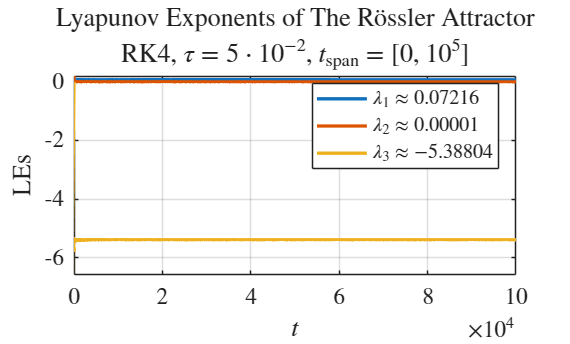

set(groot, "defaultAxesTickLabelInterpreter", "latex");
set(groot, "defaultTextInterpreter", "latex");
set(groot, "defaultLegendInterpreter", "latex");
set(groot, "defaultColorbarTickLabelInterpreter", "latex");

close
figure

plot(tsol, lyap_exp, "LineWidth", 2)
grid on;
box on;
axis tight
xlabel('$t$', 'FontSize', 14);
ylabel('LEs', 'FontSize', 14);
title(['Lyapunov Exponents of The R\"ossler Attractor', "RK4, $\tau = 5 \cdot 10^{-2}, ~t_{\mathrm{span}} = [0,~ 10^{5}]$"], 'FontSize', 14);
legend(compose("$\\lambda_{%d} \\approx %.5f$", (1:3) .', LEs), 'FontSize', 12, 'Location', 'best')
set(gca, "FontSize", 14)

% exportgraphics(gcf, "images\LEs_plot.svg", "ContentType","vector")

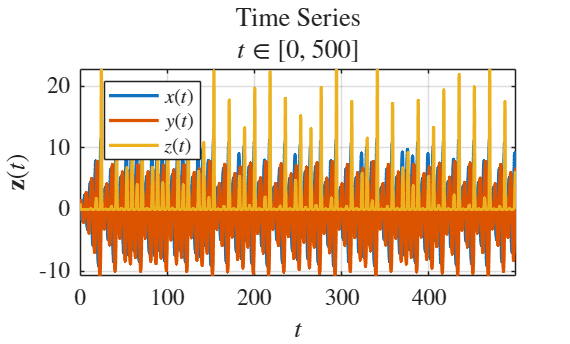

close
figure

plot(tsol(1:1e4), zsol(1:1e4, 1:3), "LineWidth", 2)
grid on;
box on;
axis tight
xlabel('$t$', 'FontSize', 14);
ylabel('$\mathbf{z}(t)$', 'FontSize', 14);
title(["Time Series" "$t\in[0,~ 500]$"], 'FontSize', 14)
legend(["$x(t)$" "$y(t)$" "$z(t)$"], 'FontSize', 12, 'Location', 'best')
set(gca, "FontSize", 14)

% exportgraphics(gcf, "images\time_series.svg", "ContentType","vector")

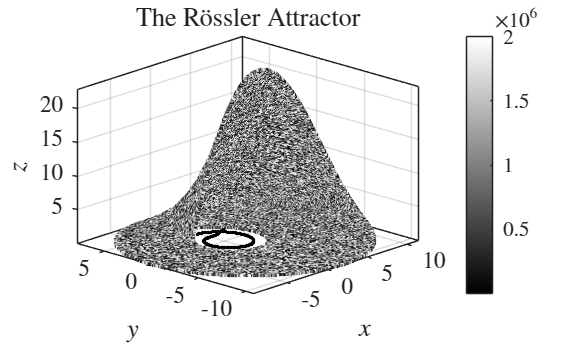

figure
scatter3(zsol(:, 1), zsol(:, 2), zsol(:, 3), 4, 1:numel(tsol), 'filled');
view([-46.8 25.2])
colormap gray;
colorbar;
axis tight;
grid on;
box on;
xlabel('$x$', 'FontSize', 14);
ylabel('$y$', 'FontSize', 14);
zlabel('$z$', 'FontSize', 14);
title('The R\"ossler Attractor', 'FontSize', 16);
set(gca, "FontSize", 14)

% exportgraphics(gcf, "images\The_Rossler_Attractor.png", "ContentType","image", "Resolution", 600)